# IOGA and Differential Equations

IOGA is an acronym for how chemical engineers track the contents of their system. IOGA is also known as material balances, mass balances, energy balances, or population balances. Ordinary differential equations (ODEs) are the result when the system is not at steady state, so that the accumulation term may be non-zero. Other fields may call development of these ODEs as compartment analysis or population dynamics.

I=How much comes **into** the system

O=How much is going **out** from the system 

G=How much is **generated**/consumed in the system

A=How much is **accumulated** in the system

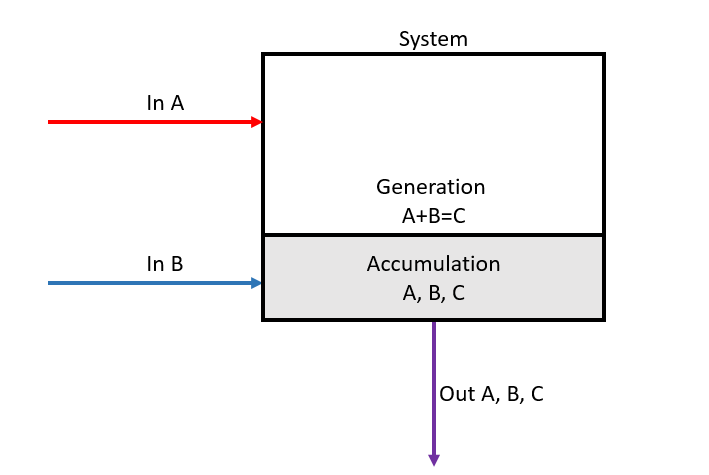

Chemical engineers use IOGA to develop differential equations that allow them to predict what is in their system. Differential equations are equations that relate a one or more functions and their derivatives. A derivative is the rate some variable changes with respect to another. If we look at our system above, we can create differential equations to describe how the system variables changes over time. We are focusing on understanding how the concentration of each species (A, B, C) changes with time. That is assuming we know the rate parameters:

$a_{1}=0.6 \frac{M}{hr}$, $b_{1}=0.6\frac{1}{Mhr}$, $c_{1}=0.1 \frac{M}{hr}$, $a_{2}=0.2 \frac{M}{hr}$, $c_{2}=0.2 \frac{M}{hr}$, $c_{3}=0.2 \frac{M}{hr}$.

We also need to know the initial conditions. At the start of the simulation at $t=0$, $C_A=6$ M, $C_B=3$, and $C_C=0.$ Positive values account for in or generation terms, and negative values account for consumption (degradation) and out terms.


$$\frac{dC_A}{dt}=a_{1}-b_{1}C_AC_B-c_{1}$$



$$\frac{dC_B}{dt}=a_{2}-b_{1}C_AC_B-c_{2}$$



$$\frac{dC_C}{dt}=b_{1}C_AC_B-c_{3}$$


Let's write this in code and solve it for a 10 hour period.

## Solving differential equations

We can use MATLAB to solve the system of differential equations. This will allow us to know the concentrations of the species in the system for the time range. Note that when writing this code the call for the ODE solver (the line that includes **ode45**) must go before the ODE function. In fact, the ODE function needs to be placed at the end of the code.

Setting up the inputs

% Let's set the time range
% Note: these times may change for each problem
tinitial = 0; %h 
tfinal = 10; %h
numberOfTimes = 101;
t=linspace(tinitial, tfinal, numberOfTimes); %t is the time

% We also need to set the initial conditions
% Note: the Ci initial condition vector has three entries because we have three ODEs. 
% If only one ODE, then Ci = [firstvalue]; 
% If two ODEs, the Ci = [ firstvalue, secondvalue];
Ci=[6, 3, 0]; %C_A at time 0=6 M
              %C_B at time 0=3 M
              %C_C at time 0=0 M

call the ODE solver

% For this example we are going to call the built-in function ode45 that
% solves ODEs
soln=ode45(@ODEs,t,Ci); % soln is the vector that stores the calculated values for each timestep
                        % @ODEs calls the function that defines the system
                        % of equations, which we need to update if we want
                        % to solve a different system of equations

% Here we pull the concentrations out from the soln vector. This allows us
% explore the solution and graph it
% Note: the variable names on the left hand sides of the equations can be
% renamed.
% Note: the 1, 2, 3 are for the three variables. If you have N variables,
% you only have N outputs for deval(soln,t,i) for i = 1 to N.
  C_A=deval(soln,t,1);
  C_B=deval(soln,t,2); 
  C_C=deval(soln,t,3);

Now let's graph the concentrations

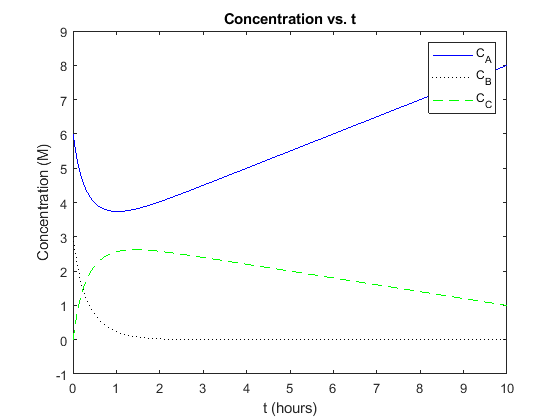

%Start a figure
figure(1)
% Note: update the plot variable names to match the oupts from the previous
% section
  plot(t,C_A,'b-')
  xlabel('t (hours)')
  ylabel('Concentration (M)')
  title('Concentration vs. t')
  hold on %Plot more than one line on the same axis
  plot(t,C_B,'k:')
  plot(t,C_C,'g--')
  legend('C_A', 'C_B', 'C_C')
  hold off

Note that we have different line styles and colors in the plots. The general plot formatting options are 

- Colors: black 'k', green 'g', red 'r', blue 'b', magenta 'm',  cyan blue 'c', yellow 'y'.

- Line types: '-' solid line, '--' dashed line, '-.' dash-dot line, ':' dotted line.

- Colors and line styles can be combined as 'r:' or 'k-.' for a red dotted line or a black dash-dot line.

- See this webpage for more details: [https://www.mathworks.com/help/matlab/ref/plot.html](https://www.mathworks.com/help/matlab/ref/plot.html) 

Lastly, we need to write the function that defines the system of ODEs that we want to solve

  function derivVector=ODEs(t,y) %must be (denominator, numerators)
   
   % Note: this entire section depends on the constants and variables and
   % differential equations and is customized for each problem.
   
    % Set parameters also known as rate constants. Use comments to indicate
    % the units for each after giving the values
    a1=0.6; % M/hr
    b1=0.6; % 1/Mhr
    c1=0.1; % M/hr
    a2=0.2; % M/hr
    c2=0.2; % M/hr
    c3=0.2; % M/hr    
        
    % Assign y's to the correct species
    % If there are more or fewer variables, then update the structure as
    % variablename = y(i) for i = 1 to N
    C_A =y(1);
    C_B =y(2);
    C_C =y(3);
    
    % If you need any algebraic relationships, type them in here
    T = C_A*C_B; % unnecessary example
    
    % ODEs
    % Note: change this list to match the differential equations. Make sure
    % that your variable names match those listed above. Do not include
    % spaces in any of the variable names and do not use / for dC/dt.
    dC_Adt=a1-b1*T-c1;
    dC_Bdt=a2-b1*C_A*C_B-c2;
    dC_Cdt=b1*C_A*C_B-c3;
    
    % Derivatives vector 
    % edit this list to include one entry for each differential equation
    % and it must be in the same order as the initial condition vector
    derivVector = [dC_Adt, dC_Bdt, dC_Cdt]'; %The ' is very important as it properly shapes the vector for the ODE solver
    end